# Eye Orientation Mapping

**Note**** : the use of quaternion-related functions in the code REQUIRES the add-on *****Robotics System Toolbox***** (Home Tab -> Add-Ons -> Get Add-Ons)**

**"****The procedure can be summarized as follows**:

- Compute gaze direction vector, s **DONE** (Theo)

- Compute unit axis vector, n (falls on Listing's plane), and angle of the rotation, θ **DONE** (Theo)

- Assemble unit quaternion q **DONE** (Theo) **CORRECTED** (Greg)

- Compute location of insertion points, i, of each EOM after the rotation according to quaternion product **DONE **(Theo)

- Compute angle θt between vector from center of the globe to tangency point and vector from the center, C, to the origin, O, of the EOM** DONE** (Theo)

- Compute angle θi between vector from center of the globe to insertion point and vector from the center to the origin of the EOM** DONE** (Theo)

- Compute arc length of EOM segment wrapped around the globe, Ls =r(θi – θt); refer to figure 2 **DONE** (Theo)

- Compute length of EOM segment from tangency point to origin of the muscle, Lt **DONE** (Theo)

- Compute deformation of EOM, (delta_L = (Ls + Lt) - Lo), where Lo is the EOM length at primary position."** DONE** (Theo)

- The centre of the eye (0,0,0), the insertion point and the origin point for a given muscle fall on a shared plane. The tangency point for that muscle also falls on this plane. We also know the magnitude of the vector describing the position of each tangency point (r=12). We also know the angle between the vector describing the position of each tangency point and the vector describing the position of the origin point (θi). Using this information calculate the coordinates of the tangency point for each muscle (and confirm they are unchanged for any gaze direction)

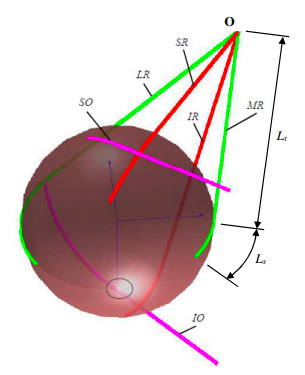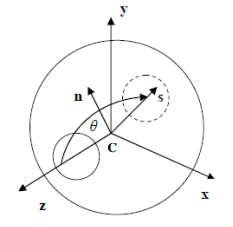

Suarez, C., 2018. *Isodeformation Curves Of The Extraocular Muscles From The Inverse Kinematics Of A Cable-Driven Parallel Kinematics Mechanism Model Of The Eye*. [online] Redalyc.org. Available at: <https://www.redalyc.org/jatsRepo/849/84959055022/html/index.html> [Accessed 16 November 2020].

close all; clear all; clc

Store EOM insertion coordinates (relative to centre of eyeball) and eyeball radius

SR = [0 ; 10 ; 6.65];
IR = [0 ; -10 ; 6.65];
LR = [-10 ; 0 ; 6.65];
MR = [9.65 ; 0 ; 7.14];
SO = [-2.65 ; 11 ; -4];
IO = [-9 ; 0 ; -7.94];

% Note: 

% x-axis
% Medial    = +ve
% Lateral   = -ve

% y-axis
% Superior  = +ve
% Inferior  = -ve

% z-axis
% Anterior  = +ve
% Posterior = -ve

% Store in an array for reasons that become clear once we rotate
EOM = [SR , IR , LR , MR , SO , IO];

% Store eyeball radius (=12mm)
r = 12;

Store EOM origin coordinates (relative to centre of eyeball)

% Origin of SR,IR,LR,MR (=Annulus of Zinn)
OZINN = [15 ; 0 ; -32];

% Origin of of SO
OSO = [15 ; 12 ; 8];

% Origin of IO
OIO = [11 ; -15 ; 11];


Store length of each EOM at primary position (necessary for the last step)


Lo = zeros(6,1);      %[SR , IR , LR , MR , SO , IO];

for i = 1:6
 
  % Compute angle thetaT - Origin used in calculation differs depending on EOM
  
  if i == 5 % EOM = SO
      thetaT = acos(r/norm(OSO));
      
  elseif i == 6 % EOM = IO
      thetaT = acos(r/norm(OIO));
      
  else % EOM = SR || IR || LR || MR
      thetaT = acos(r/norm(OZINN));
      
  end
  
  % Compute angle thetaI - Origin used in calculation differs depending on EOM

  if i == 5 % EOM = SO
      thetaI = acos(dot(EOM(:,i),OSO) / (norm(EOM(:,i))*norm(OSO)));
      
  elseif i == 6 % EOM = IO
      thetaI = acos(dot(EOM(:,i),OIO) / (norm(EOM(:,i))*norm(OIO)));
      
  else % EOM = SR || IR || LR || MR
      thetaI = acos(dot(EOM(:,i),OZINN) / (norm(EOM(:,i))*norm(OZINN)));
      
  end
  
  
  % Compute arc length of EOM segment wrapped around globe
  Ls = r*(thetaI - thetaT);
  
  % Compute length of EOM segment from tangency point to origin
             
  if i == 5 % EOM = SO
      Lt = sqrt( norm(OSO)^2 - r^2  );
      
  elseif i == 6 % EOM = IO
      Lt = sqrt( norm(OIO)^2 - r^2  );
      
  else % EOM = SR || IR || LR || MR
      Lt = sqrt( norm(OZINN)^2 - r^2  );
      
  end              
  
  % Compute initial length of EOM
  Lo(i) = (Ls + Lt);
  
end


Initialize 41x41 matrices containing deformation values for each EOM. Initialize X and Y matrices containing position coordinates (for plotting).

**Note 1**: The position of the elements corresponds to the {thetaV,thetaH} combination, such that deform_EOM(1,1) -> -20**°**,-20**°** and deform_EOM(41,41) -> +20**°**,+20**°**

**Note 2**: The dimensions of X and Y require changing if the resolution of the angle (ie the step increment in the for loops with thetaH and thetaV) is changed

deform_SR = zeros(61,61);
deform_IR = zeros(61,61);
deform_LR = zeros(61,61);
deform_MR = zeros(61,61);
deform_SO = zeros(61,61);
deform_IO = zeros(61,61);

X = [-30:30];
Y = [-30:30];


Main algorithm

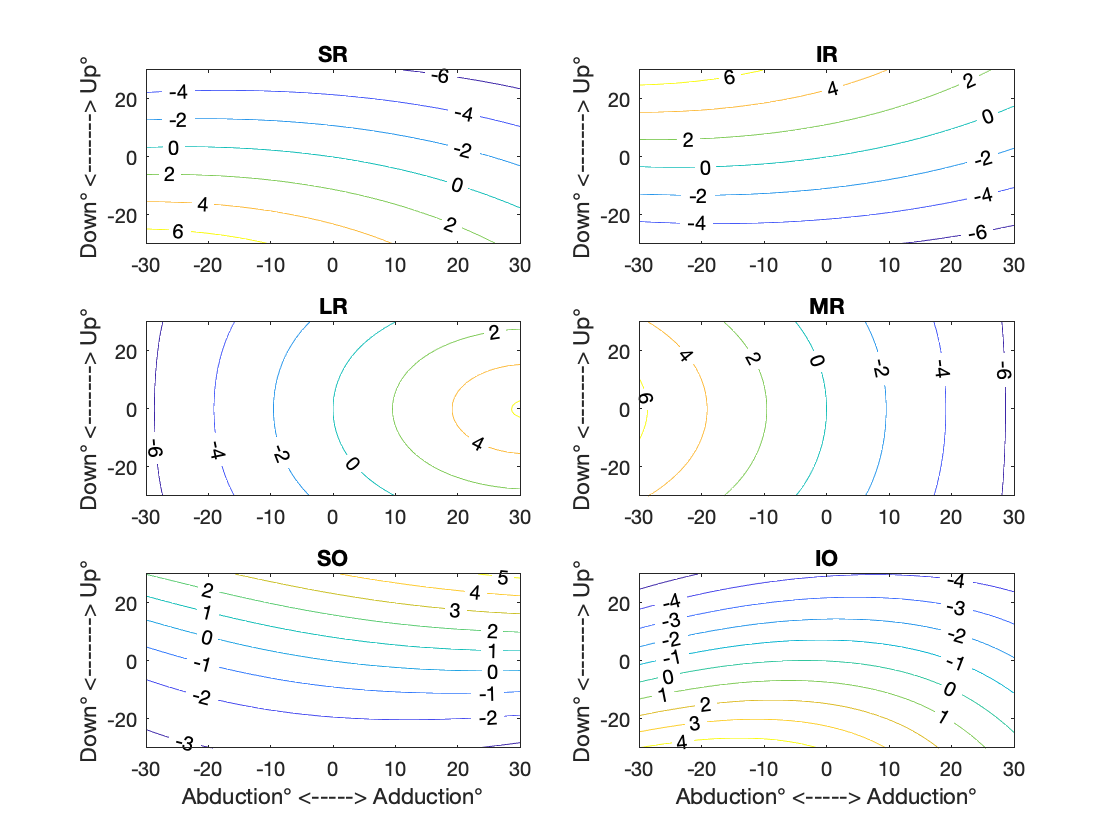

% Iterate through each degree between -20 and +20
% (decrease step size for increased resolution)
for thetaH = -30 : 1 : 30
    for thetaV = -30 : 1 : 30
         
        % Set position in 41x41 array (+21 so we get index [1] for thetaV or thetaH = -20)
        posH = thetaH + 31;
        posV = thetaV + 31;
        
        % Convert both angles to radians
        thetaHrad = thetaH * (pi/180);
        thetaVrad = thetaV * (pi/180);

        % Neutral gaze direction vector (length is irrelevant as we normalize n anyways)
        z = [0 ; 0 ; 1];
        
        % Compute gaze direction vector
        s = [cos(thetaVrad) * sin(thetaHrad) ;
            sin(thetaVrad) ;
            cos(thetaVrad) * cos(thetaHrad)];
        
        % Compute unit axis vector and angle of the rotation (radians!)
        n = cross(z,s) / norm(cross(z,s));
        theta = acos( dot(z,s) / (norm(z)*norm(s)) );
        
        % Assemble quaternion Q
        q1 = n(1)*sin(theta/2);
        q2 = n(2)*sin(theta/2);
        q3 = n(3)*sin(theta/2);
        q4 = cos(theta/2);
        Q = quaternion(q4,q1,q2,q3);
        check = norm(Q);
        
        % Compute location of insertion points of each EOM after rotation 
        % (here we see why we stored EOM coordinates into array)
        
            % Preallocate for newEOM array which will contain new rotated coordinates
            temp = zeros(1,3)';
            newEOM = [temp,temp,temp,temp,temp,temp];
  
            % Loop through each muscle coordinates in EOM, perform rotation with
            % quaternion product, and store into corresponding newEOM index-element
            for i = 1:6

                  newEOM(:,i) = rotatepoint(Q,EOM(:,i)')'; 
                  
                  % Compute angle thetaT - Origin used in calculation differs depending on EOM
                  
                  if i == 5 % EOM = SO
                      thetaT = acos(r/norm(OSO));
                      
                  elseif i == 6 % EOM = IO
                      thetaT = acos(r/norm(OIO));
                      
                  else % EOM = SR || IR || LR || MR
                      thetaT = acos(r/norm(OZINN));
                      
                  end
                  
                  % Compute angle thetaI - Origin used in calculation differs depending on EOM
    
                  if i == 5 % EOM = SO
                      thetaI = acos(dot(newEOM(:,i),OSO) / (norm(newEOM(:,i))*norm(OSO)));
                      
                  elseif i == 6 % EOM = IO
                      thetaI = acos(dot(newEOM(:,i),OIO) / (norm(newEOM(:,i))*norm(OIO)));
                      
                  else % EOM = SR || IR || LR || MR
                      thetaI = acos(dot(newEOM(:,i),OZINN) / (norm(newEOM(:,i))*norm(OZINN)));
                      
                  end
                  
                  
                  % Compute arc length of EOM segment wrapped around globe
                  if abs(thetaI)>abs(thetaT)
                  Ls = r*(thetaI - thetaT);
                  end
                  % Compute length of EOM segment from tangency point to origin
                             
                  if i == 5 % EOM = SO
                      Lt = sqrt( norm(OSO)^2 - r^2  );
                      
                  elseif i == 6 % EOM = IO
                      Lt = sqrt( norm(OIO)^2 - r^2  );
                      
                  else % EOM = SR || IR || LR || MR
                      Lt = sqrt( norm(OZINN)^2 - r^2  );
                      
                  end              
                  
                  % Compute deformation of EOM
                  if abs(thetaI)>abs(thetaT)
                  DiffL = (Ls + Lt) - Lo(i);
                  end
                  
                  % Now fill the corresponding 41x41 array with the deformation value 
                  % (filled column after column because thetaV changes in this for loop)
                  if abs(thetaI)>abs(thetaT)
                  if i == 1
                      deform_SR(posV,posH) = DiffL;
                      
                  elseif i == 2
                      deform_IR(posV,posH) = DiffL;
                      
                  elseif i == 3
                      deform_LR(posV,posH) = DiffL;
                      
                  elseif i == 4
                      deform_MR(posV,posH) = DiffL;
                      
                  elseif i == 5
                      deform_SO(posV,posH) = DiffL;
                      
                  elseif i == 6
                      deform_IO(posV,posH) = DiffL;
                      
                  end
                  end
              
            end
        
        
        
    end
end


figure
subplot(3,2,1)
contour(X,Y,deform_SR,'ShowText','on')
title('SR')
ylabel('Down° <-------> Up°')
hold on 

subplot(3,2,2)
contour(X,Y,deform_IR,'ShowText','on')
title('IR')
ylabel('Down° <-------> Up°')
hold on 

subplot(3,2,3)
contour(X,Y,deform_LR,'ShowText','on')
title('LR')
ylabel('Down° <-------> Up°')
hold on 

subplot(3,2,4)
contour(X,Y,deform_MR,'ShowText','on') 
title('MR')
ylabel('Down° <-------> Up°')
hold on 

subplot(3,2,5)
contour(X,Y,deform_SO,'ShowText','on')
title('SO')
ylabel('Down° <-------> Up°')
xlabel('Abduction° <-----> Adduction°')
hold on 

subplot(3,2,6)
contour(X,Y,deform_IO,'ShowText','on')
title('IO')
ylabel('Down° <-------> Up°')
xlabel('Abduction° <-----> Adduction°')
hold off


% Write mapping to file with ',' delimeter to make transfer into Arduino
% format easier

XSR = int64(deform_SR)

X = 61×61 int64 matrix
   7   7   7   7   7   7   7   7   7   7   7   7   7   7   6   6   6   6   6   6   6   6   6   6   6   6   5   5   5   5   5   5   5   5   5   5   4   4   4   4   4   4   4   4   3   3   3   3   3   3
   7   7   7   7   7   7   7   7   7   7   7   6   6   6   6   6   6   6   6   6   6   6   6   6   5   5   5   5   5   5   5   5   5   5   4   4   4   4   4   4   4   4   4   3   3   3   3   3   3   3
   7   7   7   7   7   7   7   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   5   5   5   5   5   5   5   5   5   5   5   4   4   4   4   4   4   4   4   4   3   3   3   3   3   3   3   3
   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   5   5   5   5   5   5   5   5   5   5   5   5   4   4   4   4   4   4   4   4   4   3   3   3   3   3   3   3   3   3
   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   5   5   5   5   5   5   5   5   5   5   5   5   4   4   4   4   4   4   4   4   4   4   3   3   3 

writematrix(XSR,'dataSR.dat')